# P2 controller

clear

% P2, X2, P100 lag, L2, F200 lag, F2 lag
x_op = [50.5, 25, 194.7, 1, 208, 2];

% F1, X1, T1, F2, P100, F3, F200, T200
u_op = [10, 5, 40, 2, 194.7, 50, 208, 25];

[A, B, C, D] = linmod('plant', x_op, u_op);

Error using load_system (line 21)
No system or file called 'plant' found.

Error in load_model

Error in slprivate (line 11)
   [varargout{1:nargout}] = feval(function_name, varargin{1:end});

Error in Simulink.ModelReference.internal.ModelRefHierarchy/setRootSystem

Error in Simulink.ModelReference.internal.ModelRefHierarchy/initializeProperties

Error in Simulink.ModelReference.internal.ModelRefHierarch


[b, a] = ss2tf(A, B, C, D, 7);

% Outputs are ordered:
% T3, T2, F4, L2, F5, T201, Q200, T100, Q100, F100, P2, X2
b = b(11, :);

G = tf(b, a);

#### 45° phase margin P controller

% For finding 45° phase margin gain
margin(G * -1 * exp(-pi/4 * 1i))
% 45° phase margin controller
margin(G * -1 * 10^(57.8/20))

#### 40° phase margin PI controller

% PI controller
Kp = -1 * 10^(57.8/20);
Ti = -1/(tan(-5 * pi/180) * 0.94);
K = tf([Kp*Ti, Kp], [Ti, 0])

margin(G * K)
% Calculating P, I for simulink PID block
P = Kp;
I = Kp/Ti;

fprintf('The PI controller needs Ti = %0.4e', Ti)
fprintf('For implementing in the PID block P = %0.4e; I = %0.4e', P, I)

# Robustness to process changes

load("settling_times_parallel.mat")

L2 = settling_times(:,:,:,1);
P2 = settling_times(:,:,:,2);
X2 = settling_times(:,:,:,3);

cmap = multigradient('preset', 'div.cb.GnYlRd.7', 'length', 256);

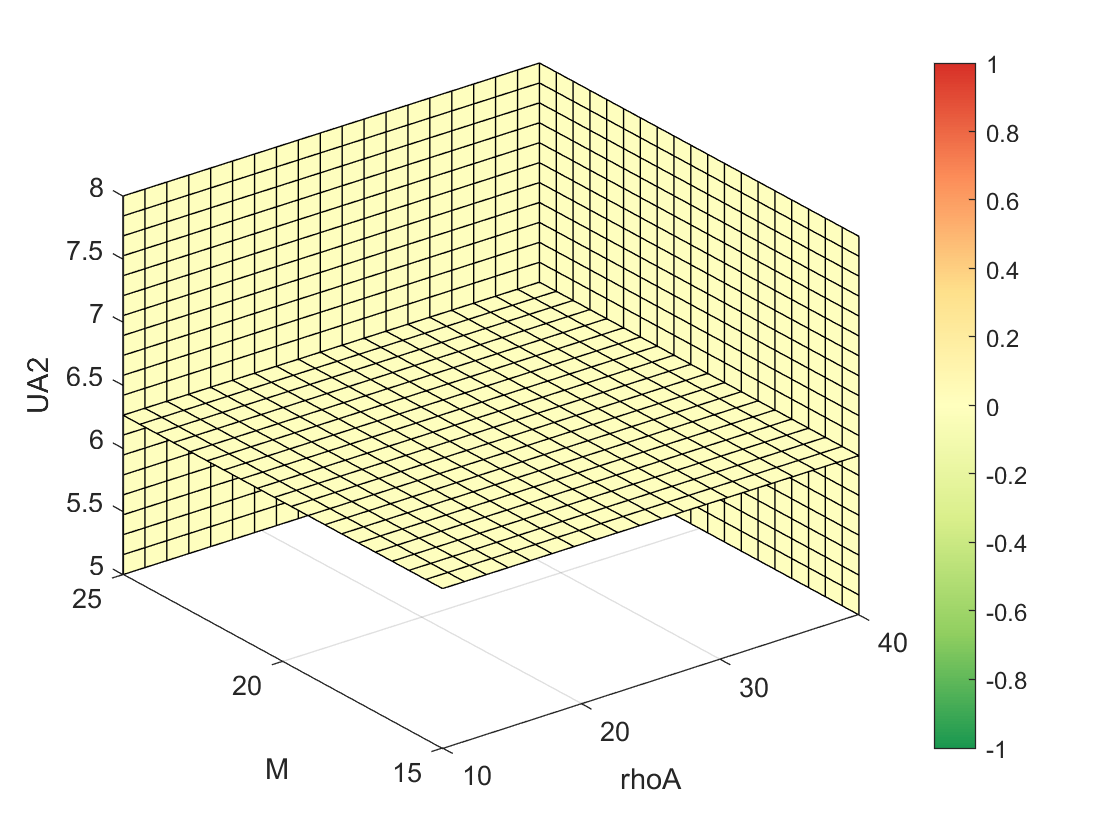

rhoA_slice = 40;
M_slice = 25;
UA2_slice =6.2632;


slice(rhoAs, Ms, UA2s, L2, rhoA_slice, M_slice, UA2_slice)
xlabel('rhoA');
ylabel('M');
zlabel('UA2');
colormap(cmap);
colorbar();

rhoAs(20)

ans = 40

Ms(20)

ans = 25

UA2s(20)

ans = 8


X2(20, 20, 20)

ans = 0

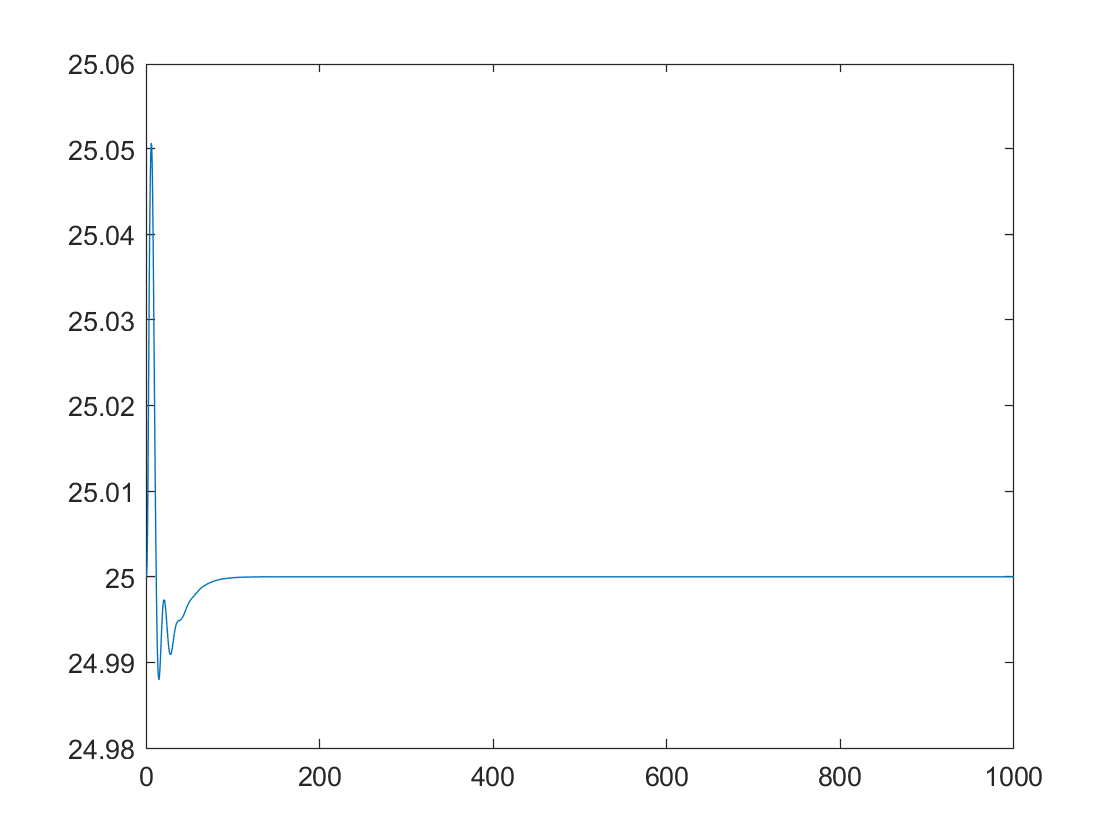

load("simOuts.mat")
sim = simOut(20,20,20);
plot(sim.tout, sim.yout(:,3))

settling_time(sim.tout, sim.yout(:,3), 25, 0.01)

ans = 0